clear

%% Lendo data-set para terino da rede
itens = load('data_set.mat').tabela1;

input = [itens.Queda, itens.Vazao]';
output = [itens.Rendimento , itens.Potencia, itens.DistribuidorD, itens.RotorD]';

%% Definições da rede para treinamento
net = feedforwardnet(40,'trainlm');

net.trainParam.epochs = 500;

net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio   = 20/100;
net.divideParam.testRatio  = 20/100;

%% Treino da rede neural
net = train(net, input, output, "useParallel", "yes",...
                'showResources', 'yes',...
                'useGPU', 'no'...
                );

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
 
Computing Resources:
Parallel Workers:
  Worker 1 on Felipe_PC, MEX on PCWIN64
  Worker 2 on Felipe_PC, MEX on PCWIN64
  Worker 3 on Felipe_PC, MEX on PCWIN64
  Worker 4 on Felipe_PC, MEX on PCWIN64
  Worker 5 on Felipe_PC, MEX on PCWIN64
  Worker 6 on Felipe_PC, MEX on PCWIN64
  Worker 7 on Felipe_PC, MEX on PCWIN64
  Worker 8 on Felipe_PC, MEX on PCWIN64
  Worker 9 on Felipe_PC, MEX on PCWIN64
  Worker 10 on Felipe_PC, MEX on PCWIN64
  Worker 11 on Felipe_PC, MEX on PCWIN64
  Worker 12 on Felipe_PC, MEX on PCWIN64
 


%% Usando a rede para prever os dados
predicted = net(input)

predicted =    56.4138   58.6678   61.0201   63.3958   65.8019   68.1478   70.4262   72.5396   74.4826   76.1942   77.7101   79.0214   80.1738   81.1679   82.0189   82.7961   83.5552   84.3494   85.1375   85.8655   86.4601   86.9167   87.2496   87.4951   87.6638   87.7665   87.8125   87.8174   87.7909   87.7341   87.6441   87.5143   87.3446   87.1327   86.8861   86.6048   86.2997   85.9703   85.6276   85.2688   84.9024   84.5208   84.1273   83.7070   83.2589   82.7656   82.2268   81.6527   81.0479   80.4501
    3.3752    3.9602    4.5986    5.2787    6.0104    6.7719    7.5655    8.3620    9.1641    9.9514   10.7420   11.5275   12.3250   13.1214   13.9032   14.6904   15.4826   16.3045   17.1333   17.9656   18.7680   19.5492   20.2976   21.0343   21.7494   22.4592   23.1522   23.8437   24.5213   25.1967   25.8551   26.5067   27.1374   27.7585   28.3582   28.9486   29.5197   30.0843   30.6334   31.1792   31.7117   32.2401   32.7508   33.2485   33.7183   34.1655   34.5856   34.9789   35.3

%% Inicio do cálculo de erros
MAE = sqrt(mean(output'-predicted').^2)

MAE =     0.0020    0.0003    0.0016    0.0004


RMSE = sqrt(mean((output'-predicted').^2))

RMSE =     0.0559    0.0218    0.0471    0.0325


R = []


R =

     []



for i = 1:size(output,1)
    mdl = fitlm(output(1,:)',predicted(1,:)')
    R = [R,mdl.Rsquared.Adjusted]
end

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   ________    __________    ______    ________

    (Intercept)    0.04425       0.024169    1.8308    0.067364
    x1             0.99953     0.00026704      3743           0


Number of observations: 1243, Error degrees of freedom: 1241
Root Mean Squared Error: 0.0559
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 1.4e+07, p-value = 0

R = 0.9999

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   ________    __________    ______    ________

    (Intercept)    0.04425       0.024169    1.8308    0.067364
    x1             0.99953     0.00026704      3743           0


Number of observations: 1243, Error degrees of freedom: 1241
Root Mean Squared Error: 0.0559
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 1.4e+07, p-value = 0

R =     0.9999    0.9999


mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   ________    __________    ______    ________

    (Intercept)    0.04425       0.024169    1.8308    0.067364
    x1             0.99953     0.00026704      3743           0


Number of observations: 1243, Error degrees of freedom: 1241
Root Mean Squared Error: 0.0559
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 1.4e+07, p-value = 0

R =     0.9999    0.9999    0.9999


mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   ________    __________    ______    ________

    (Intercept)    0.04425       0.024169    1.8308    0.067364
    x1             0.99953     0.00026704      3743           0


Number of observations: 1243, Error degrees of freedom: 1241
Root Mean Squared Error: 0.0559
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 1.4e+07, p-value = 0

R =     0.9999    0.9999    0.9999    0.9999


Error = table(MAE', RMSE',R')

Error = 4×3 table
       Var1         Var2       Var3  
    __________    ________    _______

     0.0019857    0.055911    0.99991
    0.00028853    0.021766    0.99991
     0.0015973    0.047133    0.99991
    0.00036937    0.032474    0.99991


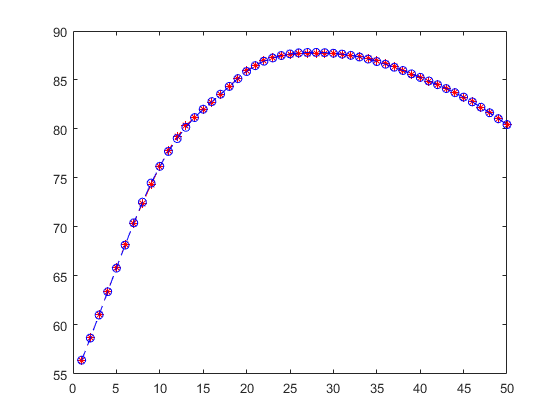

%% Erros calculados e armazenados, removendo então as variaveis inuteis
clear MAE RMSE R mdl i

fnew = figure;
plot(1:50,output(1,1:50),'r--*', 1:50,predicted(1,1:50),'b--o')

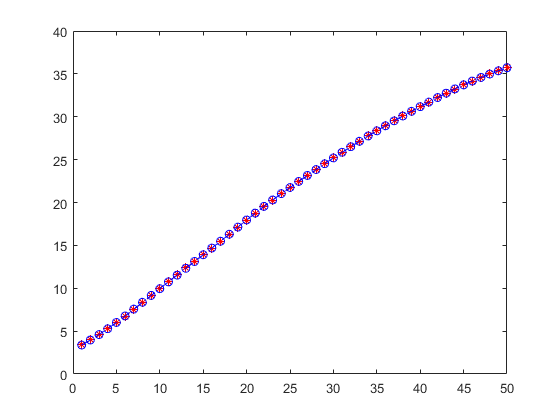

plot(1:50,output(2,1:50),'r--*', 1:50,predicted(2,1:50),'b--o')

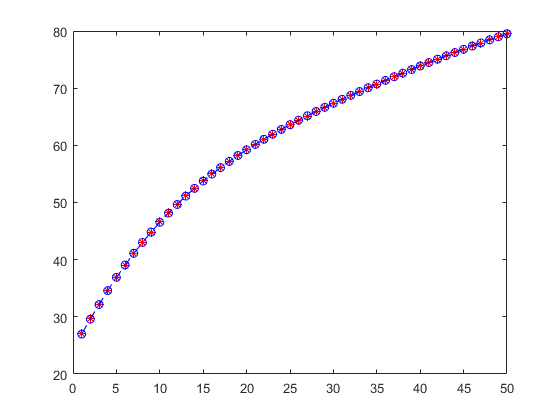

plot(1:50,output(3,1:50),'r--*', 1:50,predicted(3,1:50),'b--o')

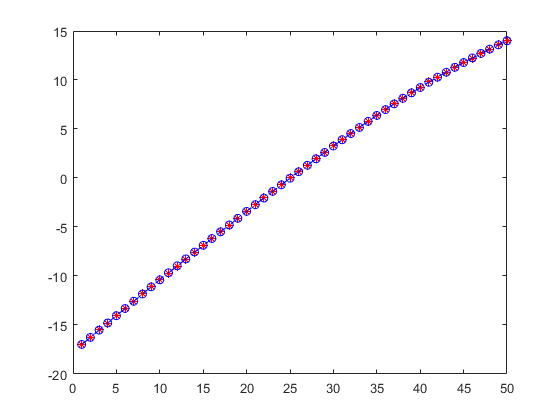

plot(1:50,output(4,1:50),'r--*', 1:50,predicted(4,1:50),'b--o')